Group project 3

Predictability of stock returns

Variables:  

  retdny:         monthly  return on the value-weighted market portfolio 

  retdny12:     yearly  return on the value-weighted market portfolio 

  retdny36:     3-year  return on the value-weighted market portfolio 

  dyny :           dividend to price ratio     

  bmny:           book-to market ratio     

  tbill :             1-month treasury bill          

%rename variables 
retdny = predict{ : ,2};
retdny12 = predict{ : ,3};
retdny36 = predict{ : ,4};
dyny = predict{ : ,5};
bmny = predict{ : ,6};
tbill = predict{ : ,7};




Q1. Run the regression of retdny as predicted by the first lag of dyny.

      Is the coefficient of dyny significant?  Is the overall regression significant? 

% create lag value of dyny
dynyL1 = lagmatrix(dyny,[1]);
x = table(dynyL1,retdny);
lm1 = fitlm(x)

lm1 = Linear regression model:
    retdny ~ 1 + dynyL1

Estimated Coefficients:
                    Estimate        SE         tStat       pValue 
                   __________    _________    ________    ________

    (Intercept)    -0.0038191    0.0066616    -0.57329     0.56673
    dynyL1             0.3989      0.18688      2.1345    0.033325


Number of observations: 463, Error degrees of freedom: 461
Root Mean Squared Error: 0.0423
R-squared: 0.00979,  Adjusted R-Squared: 0.00764
F-statistic vs. constant model: 4.56, p-value = 0.0333

Q2.  Do the residuals of this regression appear to be distributed normally, exhibit heteroskedasticity and autocorrelation? 

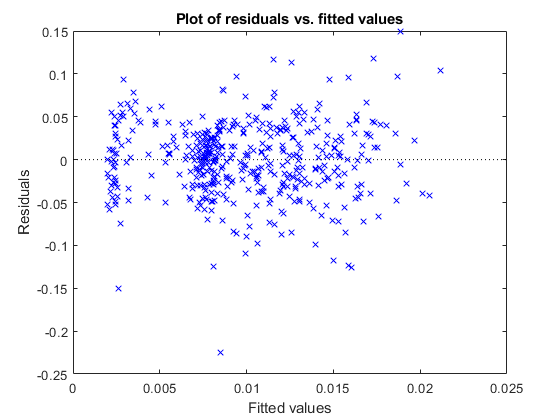

Mdl = fitlm(x);
plotResiduals(Mdl,'fitted')

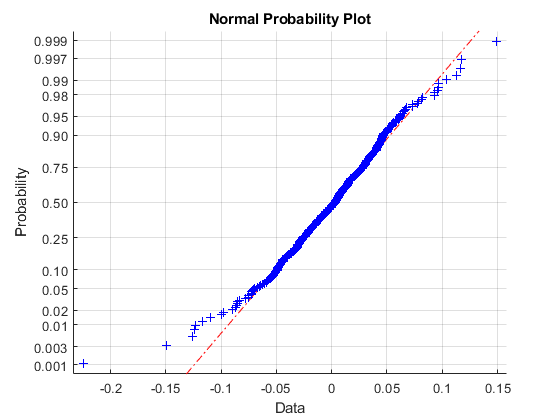

resid = Mdl.Residuals.Raw(~isnan(Mdl.Residuals.Raw));
normplot(resid)

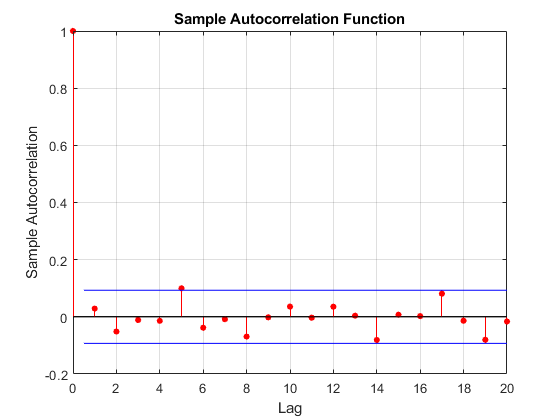

autocorr(resid)

Q3. Run the regression of retdny as predicted by the first lag of bmny

      Is the coefficient of bmny significant?  Is the overall regression significant? 

% create lag value of bmny
bmnyL1 = lagmatrix(bmny,[1]);
y = table(bmnyL1,retdny);
lm1 = fitlm(y)

lm1 = Linear regression model:
    retdny ~ 1 + bmnyL1

Estimated Coefficients:
                    Estimate         SE          tStat       pValue 
                   ___________    _________    _________    ________

    (Intercept)    -0.00044224    0.0059865    -0.073872     0.94114
    bmnyL1            0.019145     0.010602       1.8058    0.071597


Number of observations: 463, Error degrees of freedom: 461
Root Mean Squared Error: 0.0424
R-squared: 0.00702,  Adjusted R-Squared: 0.00487
F-statistic vs. constant model: 3.26, p-value = 0.0716

Q4. Run the regression of retdny as predicted by the first lag of dnny and bmny

      Are the coefficients of the predicting variables significant?  

      Is the overall regression significant? 

x = table(dynyL1,bmnyL1,retdny);
lm1 = fitlm(x)

lm1 = Linear regression model:
    retdny ~ 1 + dynyL1 + bmnyL1

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)    -0.0051285    0.0068493    -0.74876    0.45438
    dynyL1            0.91655      0.65308      1.4034    0.16116
    bmnyL1          -0.030607     0.036999    -0.82725    0.40853


Number of observations: 463, Error degrees of freedom: 460
Root Mean Squared Error: 0.0423
R-squared: 0.0113,  Adjusted R-Squared: 0.00696
F-statistic vs. constant model: 2.62, p-value = 0.074

Q5. What could account for the result in Q4?  

corrcoef(dyny,bmny)

ans =     1.0000    0.9580
    0.9580    1.0000


Q6. Run the regression of retdny as predicted by 2 lags of dnny.  

      Are the coefficients of the predicting variables significant?  

      Is the overall regression significant?   

     What can explain the difference of results using 1 instead of 2 lags of dyny?

dynyL2 = lagmatrix(dyny,[2]);
x = table(dynyL1,retdny);
lm1 = fitlm(x)

lm1 = Linear regression model:
    retdny ~ 1 + dynyL1

Estimated Coefficients:
                    Estimate        SE         tStat       pValue 
                   __________    _________    ________    ________

    (Intercept)    -0.0038191    0.0066616    -0.57329     0.56673
    dynyL1             0.3989      0.18688      2.1345    0.033325


Number of observations: 463, Error degrees of freedom: 461
Root Mean Squared Error: 0.0423
R-squared: 0.00979,  Adjusted R-Squared: 0.00764
F-statistic vs. constant model: 4.56, p-value = 0.0333

x = table(dynyL1,dynyL2,retdny);
lm1 = fitlm(x)

lm1 = Linear regression model:
    retdny ~ 1 + dynyL1 + dynyL2

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)    -0.0040684    0.0067066    -0.60662     0.5444
    dynyL1            -0.2427       1.1685     -0.2077    0.83555
    dynyL2            0.65001       1.1718     0.55471    0.57936


Number of observations: 462, Error degrees of freedom: 459
Root Mean Squared Error: 0.0424
R-squared: 0.0104,  Adjusted R-Squared: 0.00606
F-statistic vs. constant model: 2.4, p-value = 0.0914

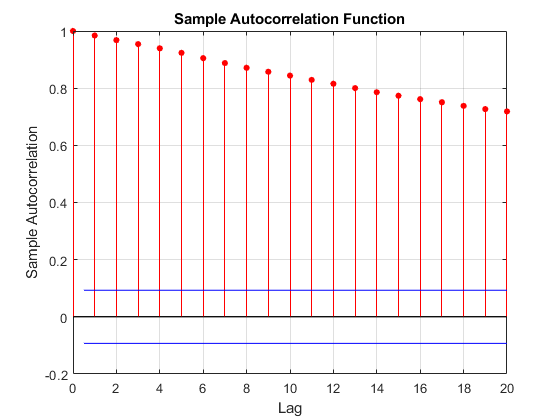

autocorr(dyny)

Q7. Run the regression of retdny12 as predicted by the 12th lag of dyny, check normality, heteroskedasticty and autocorrelation of residuals, and compute HAC standard errors.  

      Has predictability increased?   

      Is there eveidence of non-normality, heteroskedasticty and autocorrelation of residuals?  

      What is t-stat using the HAC standard errors? Is the coefficient of dyny12 significant?

dynyL12 = lagmatrix(dyny,[12])

dynyL12 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


x = table(dynyL12,retdny12);
Mdl = fitlm(x)

Mdl = Linear regression model:
    retdny12 ~ 1 + dynyL12

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)    -0.022293    0.019023    -1.1719       0.24185
    dynyL12           2.9194     0.52856     5.5233    5.6356e-08


Number of observations: 452, Error degrees of freedom: 450
Root Mean Squared Error: 0.115
R-squared: 0.0635,  Adjusted R-Squared: 0.0614
F-statistic vs. constant model: 30.5, p-value = 5.64e-08

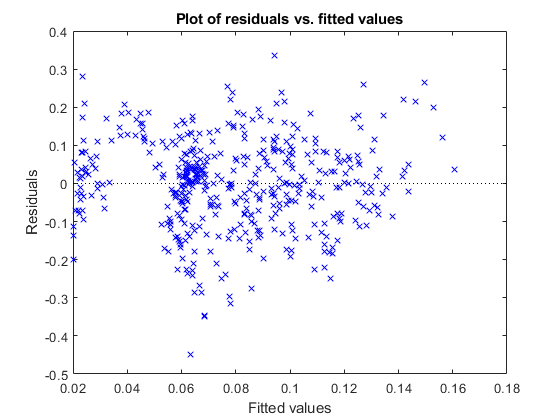

plotResiduals(Mdl,'fitted')

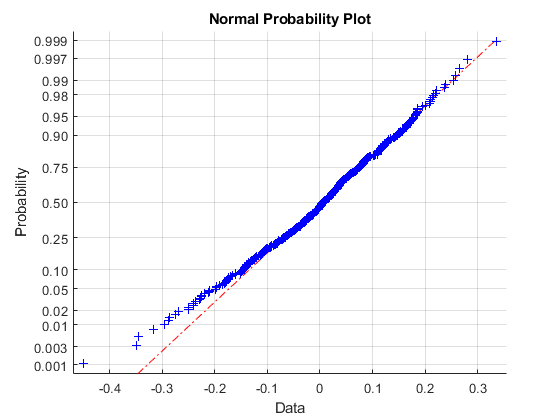

resid = Mdl.Residuals.Raw(~isnan(Mdl.Residuals.Raw));
normplot(resid)

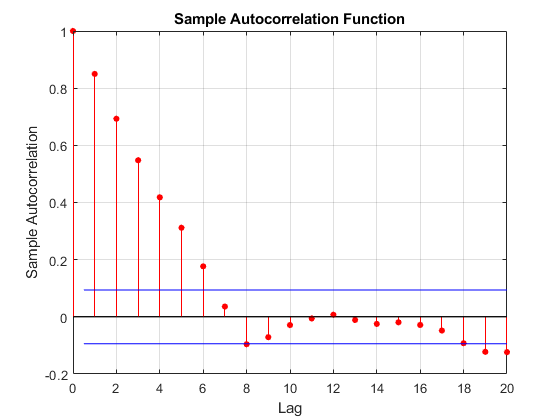

autocorr(resid)

[EstCov,se,coeff] = hac(Mdl)


Estimator type: 

HAC
Estimation method: BT
Bandwidth: 28.7741
Whitening order: 0
Effective sample size: 452
Small sample correction: on

Coefficient Covariances:

         |  Const   dynyL12 
----------------------------
 Const   |  0.0028  -0.0666 
 dynyL12 | -0.0666   1.6153 


EstCov =     0.0028   -0.0666
   -0.0666    1.6153


se =     0.0533
    1.2709


coeff =    -0.0223
    2.9194


Q8. Run the regression of retdny36 as predicted by the 36th lag of dyny, check normality, heteroskedasticty and autocorrelation of residuals, and compute HAC standard errors.  

      Has predictability increased?   

      Is there eveidence of non-normality, heteroskedasticty and autocorrelation of residuals?  

      What is t-stat using the HAC standard errors? Is the coefficient of dyny36 significant?

dynyL36 = lagmatrix(dyny,[36])

dynyL36 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


x = table(dynyL36,retdny36);
Mdl = fitlm(x)

Mdl = Linear regression model:
    retdny36 ~ 1 + dynyL36

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)    0.072532    0.063863    1.1357      0.25671
    dynyL36          4.5498      1.7353     2.622    0.0090554


Number of observations: 428, Error degrees of freedom: 426
Root Mean Squared Error: 0.34
R-squared: 0.0159,  Adjusted R-Squared: 0.0136
F-statistic vs. constant model: 6.87, p-value = 0.00906

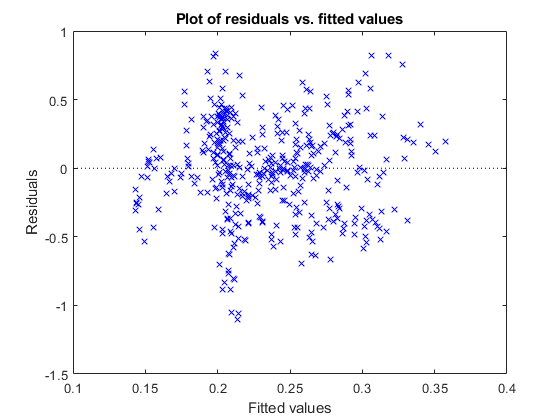

plotResiduals(Mdl,'fitted')

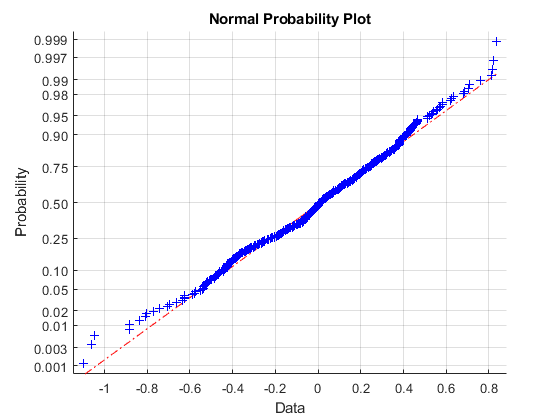

resid = Mdl.Residuals.Raw(~isnan(Mdl.Residuals.Raw));
normplot(resid)

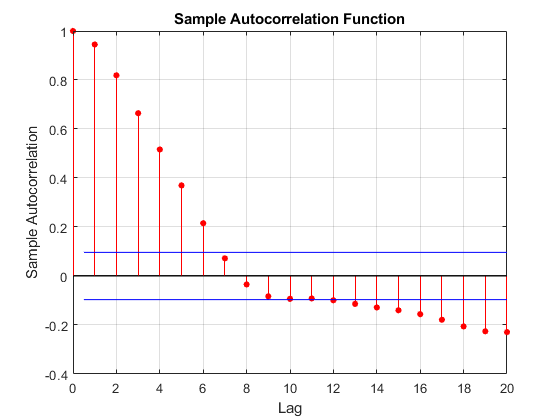

autocorr(resid)

[EstCov,se,coeff] = hac(Mdl)


Estimator type: 

HAC
Estimation method: BT
Bandwidth: 57.3264
Whitening order: 0
Effective sample size: 428
Small sample correction: on

Coefficient Covariances:

         |  Const   dynyL36 
----------------------------
 Const   |  0.0180  -0.4370 
 dynyL36 | -0.4370  11.4312 


EstCov =     0.0180   -0.4370
   -0.4370   11.4312


se =     0.1343
    3.3810


coeff =     0.0725
    4.5498
